# Finding Currents/Voltages Along Impedance Transformer

*Previously: DS16_current_in_transformer.mlx*

## Input Impedance at Each Plane

The circuit model for this demo will be two transmission line sections connected to a 50 ohm load. This problem was originally analyzed in DS15. 

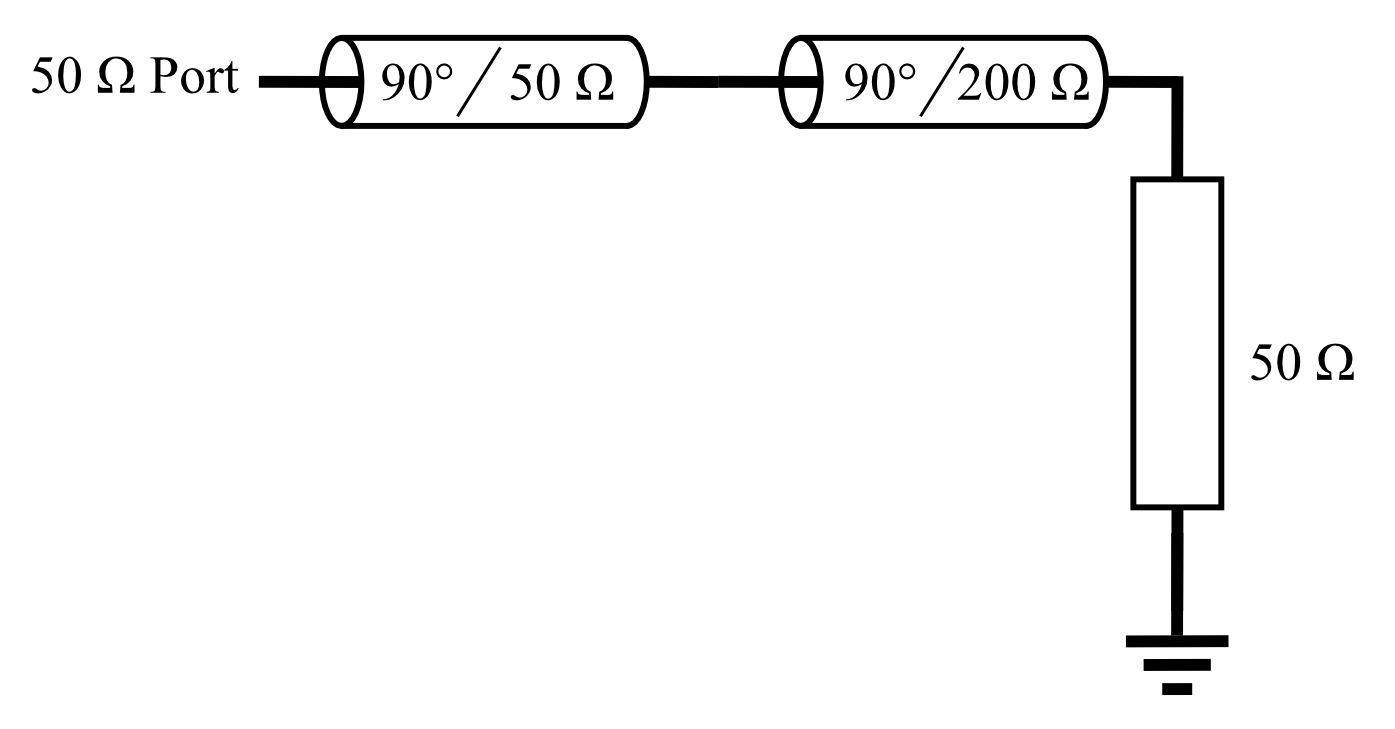

Using current transformer equations, we can find the input impedance at each plane:

%% Find input impedance for system
%
% System:
%   [50 ohm port] -- [30 ohm, 90 deg TLIN] -- [10 ohm, 90 deg TLIN] -- [ 50 ohm load]
%
% Note this V and I that will be calculated are not 'physical'. They
% represent the power, and are the V and I should it be a resistor, but in
% the physical system with weird TLIN transformers, they'll be different!

% Calculate input impedances
Z1 = xfmr2zin(200, 50, pi/2); % Transform first stage
Z2 = xfmr2zin(50, Z1, pi/2); % Transform second stage
displ("Input Impedance to 200 ohm line: ", num2fstr(Z1), " ohms");

Input Impedance to 200 ohm line: 800.00 ohms


displ("Input Impedance to 50 ohm line: ", num2fstr(Z2), " ohms");

Input Impedance to 50 ohm line: 3.13 ohms



Zin = Z2;
Vg = 1; % Pretend 1 V source, doesn't matter
Zsrc = 50; % Generator impedance

% Calculate resistive-equivalent V&I
I_res = Vg./(Zin + Zsrc);
V_res = Vg.*Zin./(Zin + Zsrc);

warning("This equation for P0 is not correct in general. You need to use eq. 2,76 from Pozar 4e");

P0 = 0.5*Vg.^2.*Zin./(Zin + Zsrc).^2; % Total power (multiplied by half because I and V were not RMS)

displ("Resistive Equivalents:");

Resistive Equivalents:


displ("  Ir = ", num2fstr(I_res.*1e3), " mA")

  Ir = 18.82 mA


displ("  Vr = ", num2fstr(V_res), " V")

  Vr = 0.06 V


Now we have this information and picture:

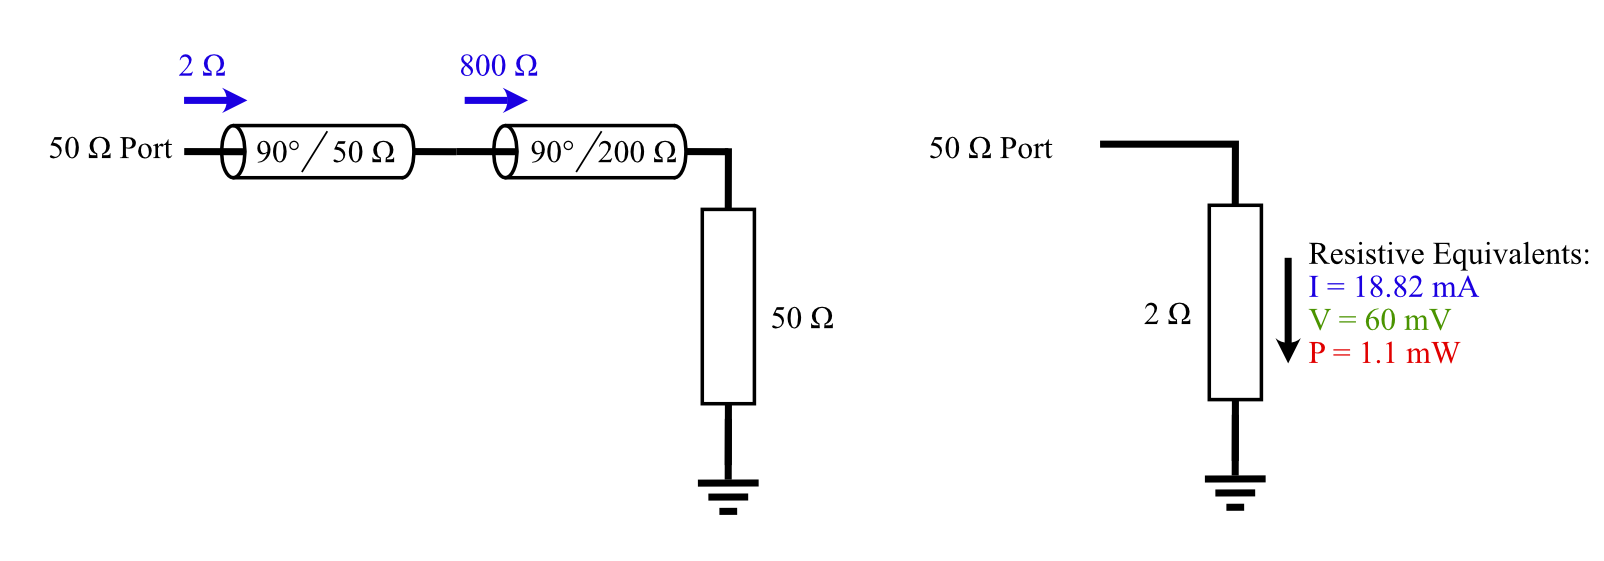

## From Resistive Equivalents, Find V & I in Different Z0 Transmission Lines

We also know that the power through the system, if we're assuming it's lossless, it constant in each transmission line. We also know that the characteristic impedance changes, so the ratio of V to I must change with it. To find Vx and Ix, the voltage and current in a given stage with characteristic impedance Z0, we can use the following equations:


$$V_{\textrm{Res}} =\frac{V_G \;\;Z_{\textrm{In}} }{Z_{\textrm{In}} +Z_{\textrm{Src}} }$$
       
$$I_{\textrm{Res}\;} =\frac{V_G }{Z_{\textrm{In}} +Z_{\textrm{Src}} }$$
     
$$P=\frac{V_G^2 \;\;Z_{\textrm{In}} }{{\left(Z_{\textrm{In}} +Z_{\textrm{Src}} \right)}^2 }$$


s.t. V and I are RMS values, and Vres and Ires are the resistive equivalent values (RMS as well). Vx and Ix (RMS) are the voltages and currents at any reference plane with power P flowing through, and Z0 as the impedance.

#### Finding Vx and Ix a Sensible but Wrong Way

Taking the power and impedance, and using V*I=P to find the max current and max voltage doesn't give you the right answer. This is because there is a phase-shift between the voltage and current that isn't captured with this method. You need to hold on to phase, otherwise the expected current levels will be too low!


$$V_X =\frac{V_G \sqrt{Z_{\textrm{In}} \;\;Z_X }}{Z_{\textrm{In}} }$$
   
$$I_X =\frac{V_G \;\sqrt{Z_{\textrm{In}} }}{\left(Z_{\textrm{In}} +Z_{\textrm{Src}} \right)\sqrt{Z_X }}$$


However, the real kicker, and the thing that confused me for a bit, is that Zx in the above equations, is *not* the characteristic impedance of the line. It is the input impedance of the rest of the system, at that point in the line. Consider for example a quarter wavelength transformer. As you look at different points of the transformer, although they all have the same characteristic impedance, each point has a different impedance looking towards the load. Crucially, **the voltage to current ratio is not the characeristic impedance, it is the impedance of the system at any given point looking towards the load.** This is what you plug in for Z0.

This is why if you look at different points along a transmission line, the current magnitudes change!

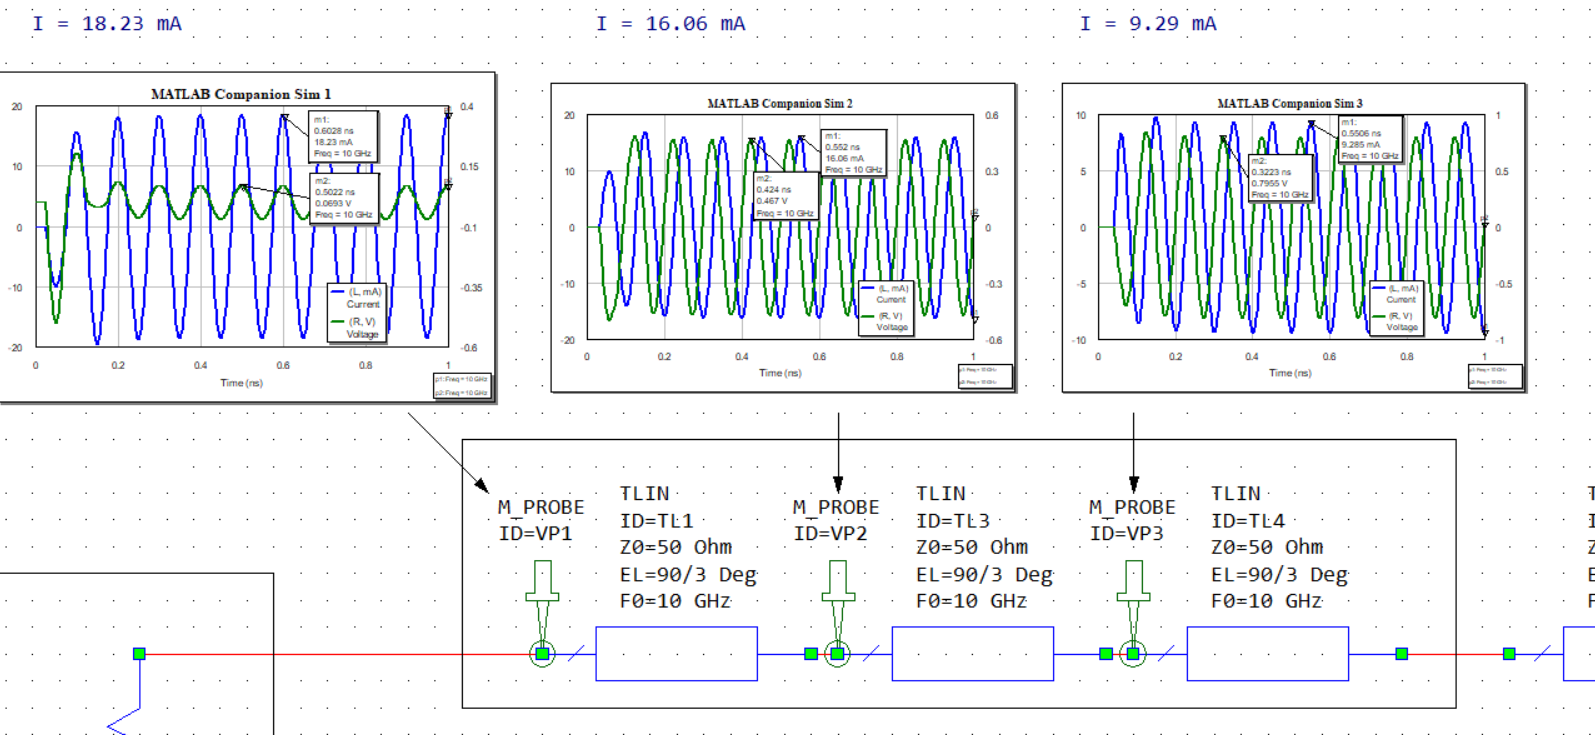

The solution is to calculate how the load impedance is transformed along each point in each transmission line. **Remember to treat the I and V vectors as phasors. You have to set the *****dot product***** of V and I to be equal to P0, not the product **(even the product of complex V and I won't cut it). 

% Distributed Zx Example, match AWR Sim

% Find impedance along 50 ohm line at 3 different points
Z2A = xfmr2zin(50, Z1, pi/2/3);
Z2B = xfmr2zin(50, Z2A, pi/2/3);
Z2C = xfmr2zin(50, Z2B, pi/2/3);

% Now find Vx and Ix at each point

% All impedance values (including load)
Z0s = [(Z2A), (Z2B), (Z2C)];

% For each stage
for Zx = Z0s
	
	% Find angle - magnitude will be wrong!
	Ix = sqrt(2.*P0/Zx); % RMS Value
	Vx = sqrt(2.*P0*Zx); % RMS Value
	
	% Find angle between vectors
	theta = angle(Ix/Vx);
	
	% Find Vx*Ix (NOT dot product)
	Px = P0/cos(theta);
	
	% Recalculate ix and Vx with correct amplitude
	Ix = sqrt(2.*Px/Zx); % RMS Value
	Vx = sqrt(2.*Px*Zx); % RMS Value

	% Print values as Magnitude + Angle, convert to amplitude from RMS
	displ("Zx = ", Zx, ":");
	displ("  Ix = ", num2fstr(Ix.*1e3), " mA");
	displ("  Vx = ", num2fstr(Vx), " V");
	
% 	% Calculate Ix and Vx
% 	Ix = sqrt(Vg^2.*Zin./Zx)./(Zin + Zsrc);
% 	Vx = sqrt(Vg^2.*Zin.*Zx)./(Zin + Zsrc);
% 	
% 	% Print values as Magnitude + Angle, convert to amplitude from RMS
% 	displ("Zx = ", Z0, ":");
	displ("  |Ix| = ", num2fstr(abs(Ix.*1e3)), " mA, Angle = ", num2fstr(angle(Ix)*180/pi));
	displ("  |Vx| = ", num2fstr(abs(Vx)), " V, Angle = ", num2fstr(angle(Vx)*180/pi));
end

Zx = 12.3552-85.265i:


  Ix = 7.16 + i*6.20 mA


  Vx = 0.62 - i*-0.53 V


  |Ix| = 9.47 mA, Angle = 40.88


  |Vx| = 0.82 V, Angle = -40.88


Zx = 4.16125-28.7174i:


  Ix = 12.33 + i*10.68 mA


  Vx = 0.36 - i*-0.31 V


  |Ix| = 16.31 mA, Angle = 40.88


  |Vx| = 0.47 V, Angle = -40.88


Zx = 3.125-1.1724e-15i:


  Ix = 18.82 mA


  Vx = 0.06 V


  |Ix| = 18.82 mA, Angle = 0


  |Vx| = 0.06 V, Angle = 0


Notice that the values for |`Ix|` and |Vx| match well with AWR's results. 

## Automating with Microsim

This still needs to be automated. The best thing I have is the code block above - you can repeat that method, which to summarize, is as follows. First, a recap on the basic equations you'll need.

Think of the current and voltage as vectors. If they're 90 degrees apart, the integral of V and I is zero; no power is disipated. This means you need their dot product:$\overrightarrow{I} \cdot \overrightarrow{V} =P_0$

#### Summary of Method:

- Calculate total input impedance. Using ABCD matricies, then collapsing to a single port by using ohms law to come up with a second equation to relate V and I at port 2, you can calculate Zin. This is done in microsim and talked about in my lab notebook. Look aroud late April 20223.

- Use total input impedance of system to find the resistive equivalent input power. Assuming a lossless system, you know this same amount of power will pass through each section of the system. You can use this to identify V and I at each section.

- At each section, find the phase shift between V and I. Even if the magnitude is wrong, using $I_{\textrm{InPhase}} =\sqrt{2\frac{P_0 }{Z_0 }}$ and $V_{\textrm{InPhase}} =\sqrt{2P_0 Z_0 }$ to find the angle between the I and V vectors is valid. Note these two complex values for I and V will contain the correct amplitude iff I and V are in phase (hence the name). 

- Find I and V by retroactively using a dot product between I and V when relating to power. This turns out to be dividing the power by cosine. $I_X =\frac{I_{\textrm{InPhase}} }{\sqrt{\cos \left(\theta \right)}}$ and $V_X =\frac{V_{\textrm{InPhase}} }{\sqrt{\cos \left(\theta \right)}}$ should give the correct final answer.